**EE 699 Next Generation Wireless Networks - Assignment 01**

Some common parameter definitions:

N_fft = 128 ;
del_F = 15 * 10 ^ 3 ;
Fs = N_fft * del_F ;
num_rf = 2 ;

- **a. PSS Detection**

- **Specifications:**

Number of Transmitters = 1 and Number of Receivers = 2

% All possible PSS sequences :
N_zc = 63 ;
PSS_freq = [] ;
mu_zc = [25, 29, 34] ;
for i = 1:3 
    x_pss = [] ;
    for n = 0: 30
        x_pss = [x_pss exp(-1j * pi * n * (n+1) * mu_zc(i) / N_zc)] ;
    end
    for n = 31: 61
        x_pss = [x_pss exp(-1j * pi * (n+1) * (n+2) * mu_zc(i) / N_zc)] ;
    end
    PSS_freq = [PSS_freq
        x_pss] ;
end
% Time domain PSS :
PSS_time = [ifft(PSS_freq(1,:), N_fft)
  ifft(PSS_freq(1,:), N_fft)
  ifft(PSS_freq(2,:), N_fft)] ;
PSS_time = circshift(PSS_time, 36, 2) ; 

% Adding the cyclic prefixes :
PSS_time = [PSS_time(1, N_fft-8:N_fft) PSS_time(1,:)
    PSS_time(2, N_fft-8:N_fft) PSS_time(2,:)
    PSS_time(3, N_fft-8:N_fft) PSS_time(3,:)] 

PSS_time =    0.0541 + 0.0608i  -0.0769 + 0.0211i   0.0141 - 0.0693i   0.0580 + 0.0315i  -0.0298 + 0.0426i  -0.0297 - 0.0240i   0.0186 - 0.0306i   0.0320 + 0.0061i   0.0118 + 0.0151i   0.0063 + 0.0274i  -0.0388 + 0.0143i  -0.0303 - 0.0391i   0.0101 - 0.0720i   0.0926 - 0.0429i   0.0737 + 0.0382i   0.0460 + 0.0495i  -0.0025 + 0.0556i   0.0194 + 0.0135i   0.0022 + 0.0688i  -0.0213 + 0.0134i  -0.0155 + 0.0513i  -0.0432 - 0.0312i   0.0481 + 0.0333i  -0.0742 + 0.0252i   0.0318 - 0.0315i  -0.0380 + 0.0599i  -0.0250 - 0.0674i   0.0595 + 0.0310i  -0.0545 + 0.0526i  -0.0535 - 0.0501i   0.0545 - 0.0432i   0.0254 + 0.0694i  -0.0663 + 0.0251i  -0.0442 - 0.0417i   0.0235 - 0.0559i   0.0492 + 0.0186i   0.0027 + 0.0412i  -0.0335 + 0.0485i  -0.0692 - 0.0002i  -0.0539 - 0.0221i  -0.0502 - 0.0690i   0.0116 - 0.0628i   0.0089 - 0.0567i   0.0513 - 0.0266i  -0.0030 - 0.0155i   0.0516 - 0.0352i   0.0053 + 0.0149i   0.0413 - 0.0403i   0.0162 + 0.0551i  -0.0253 - 0.0586i
   0.0541 + 0.0608i  -0.0769 + 0.0211i

% Sequence generation 
% Parameters
num_sf = num_rf * 10 ;
num_slots = num_sf * 2 ;
slot_duration = 0.5 * 10 ^ -3 ;
sf_duration = 2 * slot_duration ;
rf_duration = 10 * sf_duration ;

% DL waveform generation :
DL_BSignal = RFgenerator(num_rf) ;
circshift(DL_BSignal, 36, 1) ;
% Modulation :
[lteTxWaveform, info] = lteOFDMModulate(enb, DL_BSignal);
info

info = struct with fields:
           SamplingRate: 1920000
                   Nfft: 128
              Windowing: 4
    CyclicPrefixLengths: [10 9 9 9 9 9 9 10 9 9 9 9 9 9]


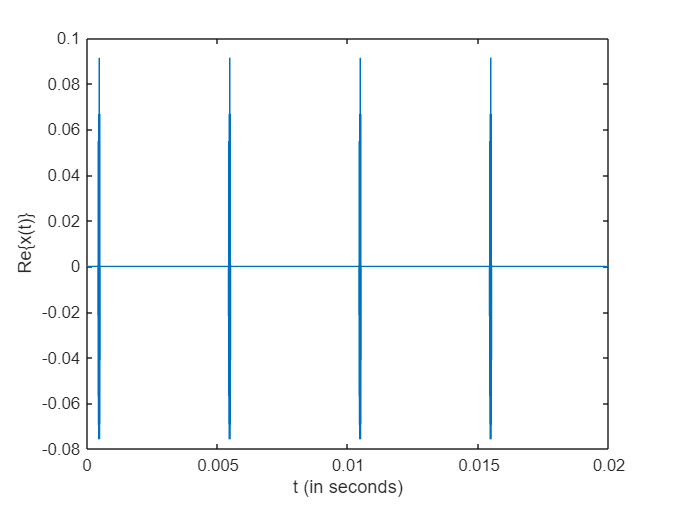

del_t = 1 / (N_fft * del_F) ; 
t_axis = 0: del_t: rf_duration * num_rf - del_t ;

% Spectrum of a subframe :
% stem(real(fft(lteTxWaveform(1:14*128, 1)))) ;

plot(t_axis, real(lteTxWaveform)); 
xlabel('t (in seconds)') ;
ylabel('Re\{x(t)\}') ;

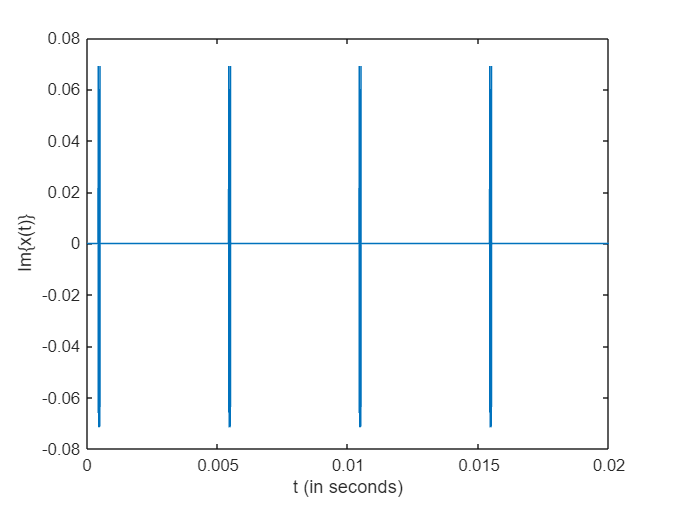

plot(t_axis, imag(lteTxWaveform)); 
xlabel('t (in seconds)') ;
ylabel('Im\{x(t)\}') ;

**Non-Coherent Detection **

i. Using Time Domain Correlation

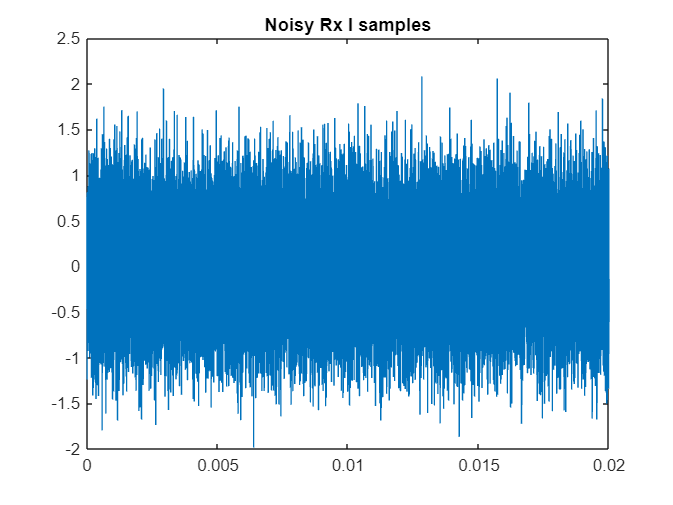

% For AWGN channel
% Adding Noise :
mu = 0 ;
sig2 = 0.5 ;
noise_samples = normrnd(mu, sig2, size(lteTxWaveform)) + 1j * normrnd(mu, sig2, size(lteTxWaveform))  ;
rx_signal = lteTxWaveform + noise_samples ; % Noisy signal 

% Visualization :
plot(t_axis,real(rx_signal));
title('Noisy Rx I samples') ;

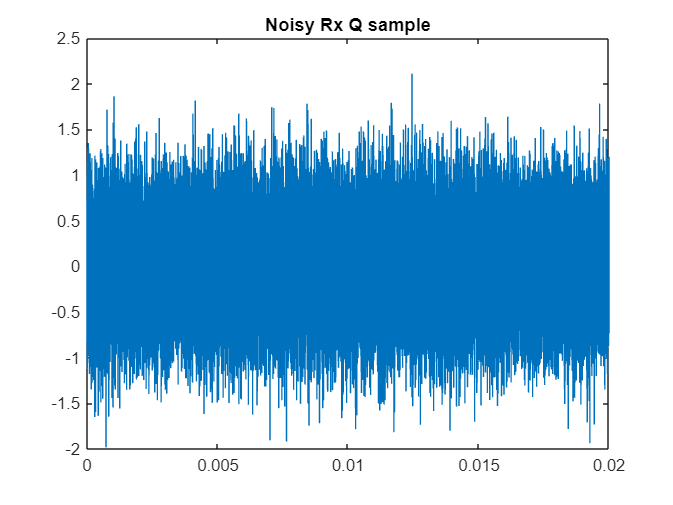

plot(t_axis, imag(rx_signal));
title('Noisy Rx Q sample') ;

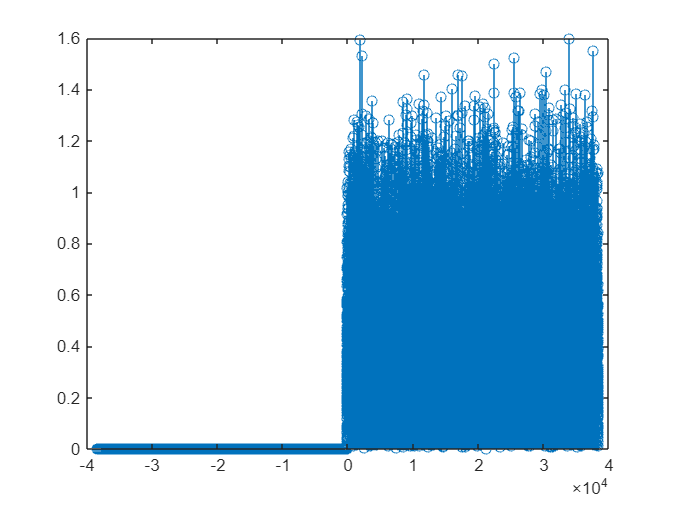

% Doing correlation : To synchronize 
[c1, lags1] = xcorr(rx_signal, PSS_time(1, :)) ;
stem(lags1, abs(c1)) ;


[c2, lags2] = xcorr(rx_signal, PSS_time(2, :)) ;
stem(lags2, abs(c2)) ;

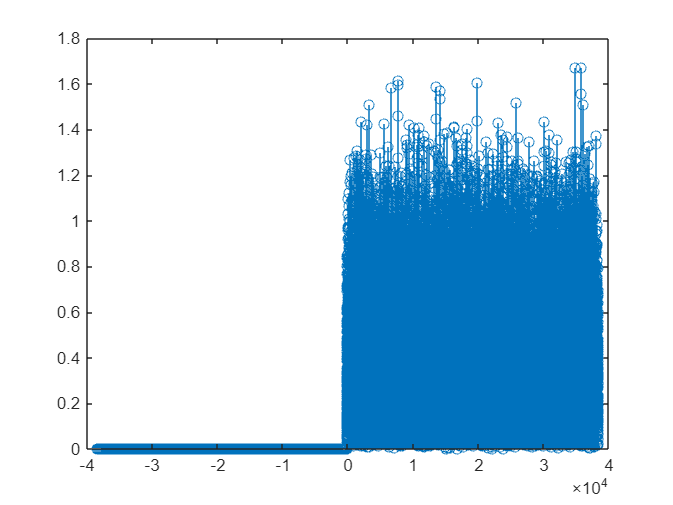


[c3, lags3] = xcorr(rx_signal, PSS_time(3, :)) ;
stem(lags3, abs(c3)) ;

% For Rayleigh channel


ii. Using Frequency Domain

% For AWGN channel 
 

% For Rayleigh channel

**Function definitions**:

function lteTxSignal = RFgenerator(numRF)
    % Cell Wide Parameters
    enb.NDLRB = 6 ; % Number of DL Resource Blocks
    enb.Cyclicprefix = 'Normal' ; % Type of CP (length)
    enb.NCellID = 0 ;
    enb.CellRefP = 1 ;
    enb.DuplexMode = 'FDD';
     
    radioFrame = [] ;
    for i=0:9
       enb.NSubframe = i ;    
        % PSS symbols and indices for antenna 1 and 2:
        pss_symbols = ltePSS(enb) ;
        antenna = 0 ;
        pss_indices = ltePSSIndices(enb, antenna) ;
        
        % One Sub frame formation :
        subframe = lteDLResourceGrid(enb);
        subframe(pss_indices) = pss_symbols;
        
        % One radio frame formation :
        radioFrame = [radioFrame subframe] ;
    end
    
    % N radio frames formation 
    lteTxSignal = [] ;
    while (numRF > 0)
        lteTxSignal = [lteTxSignal radioFrame] ;
        numRF = numRF - 1 ;
    end
end